% 加载数据
px4_data = load('px4ff.mat'); % 加载PX4的.mat文件
hofa_data = load('hofaff.mat'); % 加载HOFA的.mat文件

% 提取轨迹数据
time_px4_xy = seconds(px4_data.LocalNED_X.Time); % PX4时间
x_px4 = px4_data.LocalNED_X.Var1; % PX4 X位置
y_px4 = px4_data.LocalNED_Y.Var1; % PX4 Y位置
x_px4_ref = px4_data.LocalNEDTarget_XTarget.Var1; % 
y_px4_ref = px4_data.LocalNEDTarget_YTarget.Var1; % 
begin_idx_px4 = 310;%124;
end_idx_px4 = 495;%310;
x_px4 = x_px4(begin_idx_px4:end_idx_px4);
y_px4 = y_px4(begin_idx_px4:end_idx_px4);
x_px4_ref = x_px4_ref(begin_idx_px4:end_idx_px4);
y_px4_ref = y_px4_ref(begin_idx_px4:end_idx_px4);
error_px4=mean(sqrt((x_px4_ref-x_px4).*(x_px4_ref-x_px4)+(y_px4_ref-y_px4).*(y_px4_ref-y_px4)))

error_px4 = single
0.0900



time_hofa_xy = seconds(hofa_data.LocalNED_X.Time); % HOFA时间
x_hofa = hofa_data.LocalNED_X.Var1; % HOFA X位置
y_hofa = hofa_data.LocalNED_Y.Var1; % HOFA Y位置  

begin_idx_hofa = 338;
end_idx_hofa = 527;
x_hofa = x_hofa(begin_idx_hofa:end_idx_hofa);
y_hofa = y_hofa(begin_idx_hofa:end_idx_hofa);


time_xysetpoint = seconds(hofa_data.LocalNEDTarget_XTarget.Time);
x_ref = hofa_data.LocalNEDTarget_XTarget.Var1; % 期望 X位置（相同）
y_ref = hofa_data.LocalNEDTarget_YTarget.Var1; % 期望 Y位置（相同）
x_ref = x_ref(begin_idx_hofa:end_idx_hofa);
y_ref = y_ref(begin_idx_hofa:end_idx_hofa);

error_hofa=mean(sqrt((x_ref-x_hofa).*(x_ref-x_hofa)+(y_ref-y_hofa).*(y_ref-y_hofa)))

error_hofa = single
0.0690

% 提取姿态角数据
a = 510;
b = 1200;
time_atti = seconds(hofa_data.AttitudeEuler_Roll.Time);
time_atti = time_atti - time_atti(1);
roll_hofa = hofa_data.AttitudeEuler_Roll.Var1/pi*180; % HOFA 实际滚转角
pitch_hofa = hofa_data.AttitudeEuler_Pitch.Var1/pi*180; % HOFA 实际俯仰角
yaw_hofa = hofa_data.AttitudeEuler_Yaw.Var1/pi*180; % HOFA 实际偏航角
time_atti = time_atti(a:b);
roll_hofa = roll_hofa(a:b);
pitch_hofa = pitch_hofa(a:b);
yaw_hofa = yaw_hofa(a:b);

time_attiset = seconds(hofa_data.AttitudeTargetEuler_RollTarget.Time);
time_attiset = time_attiset - time_attiset(1);
roll_setpoint_hofa = hofa_data.AttitudeTargetEuler_RollTarget.Var1/pi*180; % HOFA 设定滚转角
pitch_setpoint_hofa = hofa_data.AttitudeTargetEuler_PitchTarget.Var1/pi*180; % HOFA 设定俯仰角
yaw_setpoint_hofa = hofa_data.AttitudeTargetEuler_YawTarget.Var1/pi*180; % HOFA 设定偏航角
time_attiset = time_attiset(a:b);
roll_setpoint_hofa = roll_setpoint_hofa(a:b);
pitch_setpoint_hofa = pitch_setpoint_hofa(a:b);
yaw_setpoint_hofa = yaw_setpoint_hofa(a:b);
ea_hofa = mean(abs(roll_setpoint_hofa-roll_hofa)+abs(pitch_setpoint_hofa-pitch_hofa)+abs(yaw_setpoint_hofa-yaw_hofa))

ea_hofa = single
0.7209


roll_px4 = px4_data.AttitudeEuler_Roll.Var1/pi*180; % px4 实际滚转角
pitch_px4 = px4_data.AttitudeEuler_Pitch.Var1/pi*180; % px4 实际俯仰角
yaw_px4 = px4_data.AttitudeEuler_Yaw.Var1/pi*180; % px4 实际偏航角
roll_setpoint_px4 = px4_data.AttitudeTargetEuler_RollTarget.Var1/pi*180; % px4 设定滚转角
pitch_setpoint_px4 = px4_data.AttitudeTargetEuler_PitchTarget.Var1/pi*180; % px4 设定俯仰角
yaw_setpoint_px4 = px4_data.AttitudeTargetEuler_YawTarget.Var1/pi*180; % px4 设定偏航角
roll_px4 = roll_px4(a:b);
pitch_px4 = pitch_px4(a:b);
yaw_px4 = yaw_px4(a:b);
roll_setpoint_px4 = roll_setpoint_px4(a:b);
pitch_setpoint_px4 = pitch_setpoint_px4(a:b);
yaw_setpoint_px4 = yaw_setpoint_px4(a:b);
ea_px4 = mean(abs(roll_setpoint_px4-roll_px4)+abs(pitch_setpoint_px4-pitch_px4)+abs(yaw_setpoint_px4-yaw_px4))

ea_px4 = single
0.9869

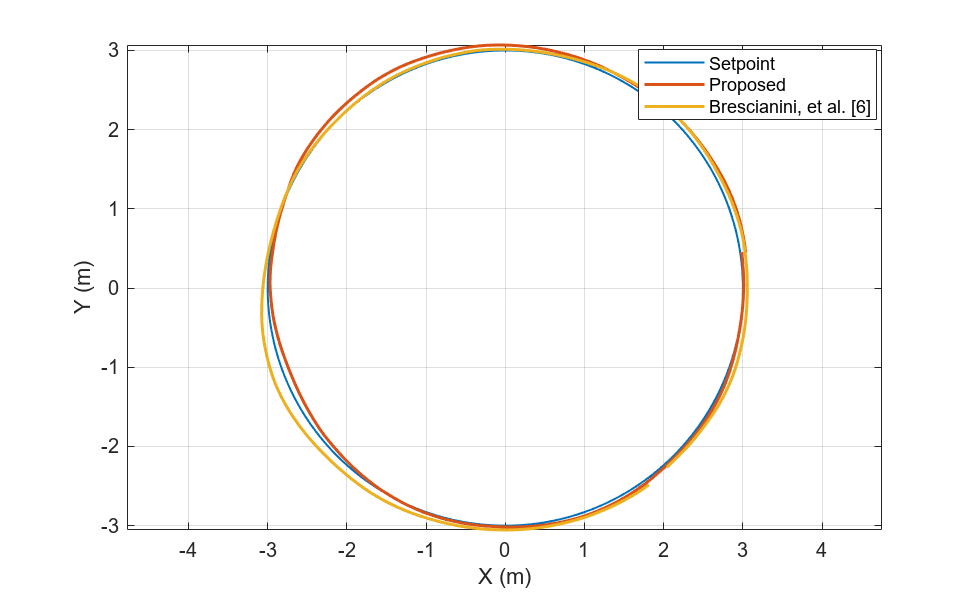


% 绘制轨迹对比图
figure;
set(figure, 'Position', [0, 0, 650, 397]);
hold on;
plot(x_ref, y_ref, 'LineWidth', 1); % 期望轨迹（黑色虚线）
plot(x_hofa, y_hofa, 'LineWidth', 1.5); % HOFA轨迹（绿色实线）
plot(x_px4, y_px4, 'LineWidth', 1.5); % PX4轨迹（蓝色实线）
xlabel('X (m)');
ylabel('Y (m)');
legend('Setpoint', 'Proposed', 'Brescianini, et al. [6]');
grid on;
box on;
axis equal;
hold off;
legend("Position", [0.65478,0.79878,0.24462,0.11849])
saveas(gcf, 'C:\Users\zzy\Desktop\爱沙尼亚\xy.eps', 'epsc');

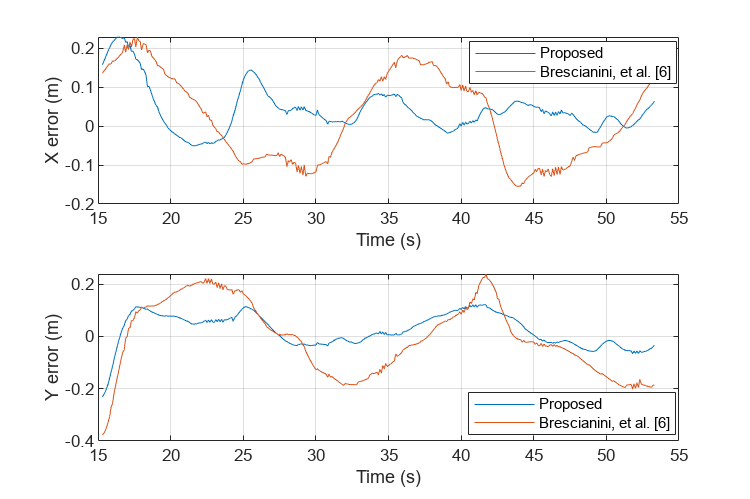




% figure;
% set(figure, 'Position', [0, 0, 650, 500]);
c=155;
d=c+380;
x_px4 = px4_data.LocalNED_X.Var1; % PX4 X位置
y_px4 = px4_data.LocalNED_Y.Var1; % PX4 Y位置
x_hofa = hofa_data.LocalNED_X.Var1; % HOFA X位置
y_hofa = hofa_data.LocalNED_Y.Var1; % HOFA Y位置 
x_ref = hofa_data.LocalNEDTarget_XTarget.Var1; % 期望 X位置（相同）
y_ref = hofa_data.LocalNEDTarget_YTarget.Var1; % 期望 Y位置（相同）
time_hofa_xy = time_hofa_xy-time_hofa_xy(1);
% subplot(2,1,1)
% hold on
% plot(time_hofa_xy(c:d),x_ref(c:d));
% plot(time_hofa_xy(c:d),x_hofa(c:d));
% plot(time_hofa_xy(c:d),x_px4(c:d));
% xlabel('Time (s)');
% ylabel('X (m)');
% legend('Setpoint', 'Proposed', 'Brescianini');
% 
% subplot(2,1,2)
% hold on
% plot(time_hofa_xy(c:d),y_ref(c:d));
% plot(time_hofa_xy(c:d),y_hofa(c:d));
% plot(time_hofa_xy(c:d),y_px4(c:d));
% xlabel('Time (s)');
% ylabel('Y (m)');
% legend('Setpoint', 'Proposed', 'Brescianini');
% saveas(gcf, 'C:\Users\zzy\Desktop\爱沙尼亚\xandy.eps', 'epsc');

figure;
set(figure, 'Position', [0, 0, 500, 333]);
subplot(2,1,1)

plot(time_hofa_xy(c:d),x_hofa(c:d)-x_ref(c:d));
hold on
plot(time_hofa_xy(c:d),x_px4(c:d)-x_ref(c:d));
xlabel('Time (s)');
ylabel('X error (m)');
legend( 'Proposed', 'Brescianini, et al. [6]');  
grid on;
hold off;
subplot(2,1,2)

plot(time_hofa_xy(c:d),y_hofa(c:d)-y_ref(c:d));
hold on
plot(time_hofa_xy(c:d),y_px4(c:d)-y_ref(c:d));
xlabel('Time (s)');
ylabel('Y error (m)');
legend( 'Proposed', 'Brescianini, et al. [6]');
grid on;
hold off;


subplot(2,1,2)
legend("Position", [0.6243,0.12921,0.27667,0.085671])


subplot(2,1,1)
legend("Position", [0.62552,0.83166,0.27667,0.085671])
saveas(gcf, 'C:\Users\zzy\Desktop\爱沙尼亚\exandy.eps', 'epsc');

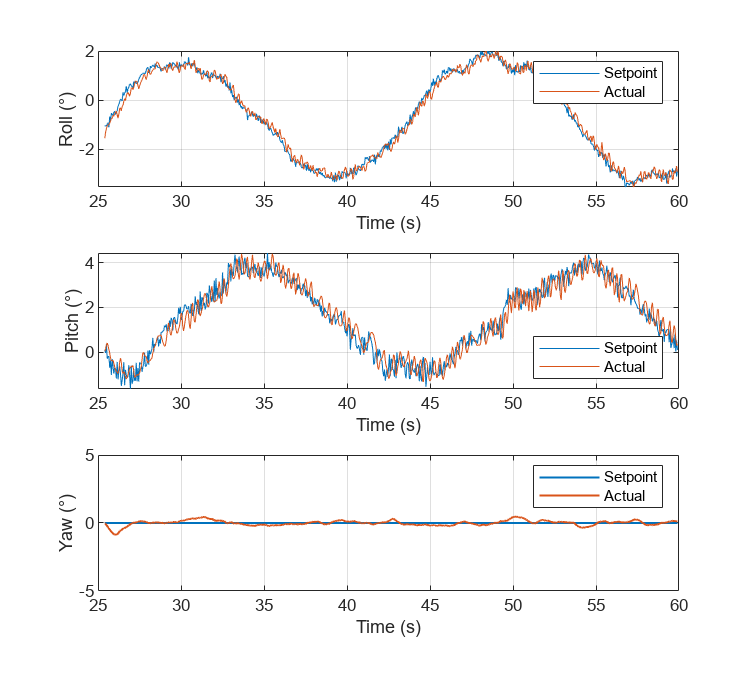



% 绘制姿态角对比图
figure;
set(figure, 'Position', [0, 0, 500, 450]);
% 滚转角
subplot(3, 1, 1);
plot(time_attiset, roll_setpoint_hofa, 'LineWidth', 0.5); % 设定值
hold on;
plot(time_atti, roll_hofa,'LineWidth', 0.5); % 实际值
ylabel('Roll (°)');
xlabel('Time (s)');
legend('Setpoint','Actual');
grid on;
hold off;

% 俯仰角
subplot(3, 1, 2);
plot(time_attiset, pitch_setpoint_hofa, 'LineWidth', 0.5); % 设定值
hold on;
plot(time_atti, pitch_hofa, 'LineWidth', 0.5); % 实际值
ylabel('Pitch (°)');
xlabel('Time (s)');
legend('Setpoint','Actual','Location', 'southeast');
grid on;
hold off;

% 偏航角
subplot(3, 1, 3);
plot(time_attiset, yaw_setpoint_hofa, 'LineWidth', 1); % 设定值
hold on;
plot(time_atti, yaw_hofa, 'LineWidth', 1); % 实际值
ylabel('Yaw (°)');
xlabel('Time (s)');
ylim([-5,5]);
legend('Setpoint','Actual');
grid on;
hold off;


saveas(gcf, 'C:\Users\zzy\Desktop\爱沙尼亚\angle.eps', 'epsc');